# Magnetic field simulations

calculates the mutual inductance interaction between a transmitting and receiving coil

- mutual inductance & coupling coefficient between the coils

- voltage and current induced in the receiving coil by the transmitting coil

- change in voltage in transmitting coil induced by the receiving coil

clear all;
close all;
addpath('lib');
% clc;

## CONSTANTS

coil geometry

- transmitter & receiver radius

- transmitter & receiver turns

- transmitter & receiver wire gauges

- receiving coil locations & orientations

- material of coil cores (relative magnetic permeability)

- (calculated) cross-sectional circular area of each coil

TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 50;    % # turns/layer
RX_NT = 20;
TX_NL = 5;     % # layers
RX_NL = 5;

TARGET_F = 1000e3; % Hz

%rx = Coil.FromWindings(RX_D, RX_NT, RX_NL, RX_AWG, TARGET_F, 0);
%tx = Coil.FromWindings(TX_D, TX_NT, TX_NL, TX_AWG, TARGET_F, 0);

rx = Coil.FromL(RX_D, RX_NT, RX_NL, RX_AWG, TARGET_F, .11e-3, 0, 1e-6);
tx = Coil.FromL(TX_D, TX_NT, TX_NL, TX_AWG, TARGET_F, .11e-3, 0, 1e-6);

RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]
theta = linspace(0, 2*pi, 360);
RX_U = [zeros(size(theta));    % receiver coil unit orientation vector
        sin(theta);
        cos(theta)];

mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

voltage source

- peak voltage

- driving AC frequency (swept)

TX_V = 23;           % voltage [V]

f = linspace(TARGET_F * .9, TARGET_F * 1.1, 1e3);    % AC frequency [Hz]
OMEGA = f * (2*pi);              % [rad/sec]

RLC characteristics

- resistance is calculated from the resistivity of copper wire gauge and the length of wire use

- coil inductance is given by:


$$L=\text{ }\frac{\mu N^2 A}{l}$$



$$\begin{array}{l}
\mu =4\pi \times {10}^{−7} ;\text{magnetic}\text{ }\text{permeability}\text{ }\text{of}\text{ }\text{human}\text{ }\text{flesh}\\
N=\text{number}\text{ }\text{of}\text{ }\text{turns}\text{ }\text{in}\text{ }\text{coil}\\
A=\text{cross}−\text{sectional}\text{ }\text{area}\text{ }\text{of}\text{ }\text{coil}\\
l=\text{length}\text{ }\text{of}\text{ }\text{coil}
\end{array}$$


             alternative formula used by a lot of online calculators:


$$L=N^2 \mu R\left\lbrack ln\left(\frac{16R}{d}\right)−2\right\rbrack$$



$$\begin{array}{l}
N=number\text{ }of\text{ }turns\text{ }in\text{ }coil\\
\mu =4\pi \times {10}^{−7} ;\text{ }magnetic\text{ }permeability\text{ }of\text{ }human\text{ }flesh\\
R=radius\text{ }of\text{ }coil\\
d=diameter\text{ }of\text{ }wire
\end{array}$$


%[TX_L, TX_R, TX_l] = Lcalc(TX_AWG, TX_D*1e3, TX_NT, TX_NL, TARGET_F*1e-3)   % resistance [Ohms] &
%[RX_L, RX_R, RX_l] = Lcalc(RX_AWG, RX_D*1e3, RX_NT, RX_NL, TARGET_F*1e-3)    % & inductance [H]
%TX_R = 100;
%TX_L = .11e-3;
%RX_L = .11e-3;

resonant frequency approximation (slightly detuned due to coupling)


$$\omega =\frac{1}{\sqrt{LC}}=2\pi f$$


        from paper about magnetic resonant inductive coupling:


$$\omega_1 =\frac{1}{L\text{ }C\left\lbrack 1−\frac{M}{L}\right\rbrack },\text{ }\omega_2 =\frac{1}{L\text{ }C\left\lbrack 1+\frac{M}{L}\right\rbrack }$$


- capacitance

%TX_C = (1/(2*pi*TARGET_F*sqrt(TX_L)))^2    % capacitance [F]
%RX_C = (1/(2*pi*TARGET_F*sqrt(RX_L)))^2    % capacitance [F]



%TX_RESF = (1 / sqrt(TX_L * TX_C)) / (2*pi)    % resonant frequency (Hz)
%RX_RESF = (1 / sqrt(RX_L * RX_C)) / (2*pi)

## magnetic field & mutual inductance

the mutual inductance is defined by:


$$M=\frac{N_2 \varphi_{21} }{I_1 }$$



$$\begin{array}{l}
\varphi_{21} =flux\text{ }through\text{ }receiver\text{ }coil\text{ }due\text{ }to\text{ }transmitter\text{ }coil\\
N_1 =number\text{ }of\text{ }turns\text{ }in\text{ }transmitter\text{ }coil\\
N_2 =number\text{ }of\text{ }turns\text{ }in\text{ }receiver\text{ }coil
\end{array}$$


since the number of turns in each coil is chosen, we merely need to find the flux through the receiver coil due to the transmitter coil. we do so by using the Biot-Savart law to calculate the magnetic field generated by the given coil at any point in space:

- magnetic field contribution of a current element:


$$\vec{dB} =\frac{\mu_0 I\vec{dL} \times \vec{1_r } }{4\pi r^2 }$$



$$\begin{array}{l}
\vec{\mathit{dL}} =infinitesimal\text{ }length\text{ }of\text{ }conductor\text{ }carrying\text{ }current\\
\vec{1_r } =unit\text{ }vector\text{ }specifying\text{ }direction\text{ }of\text{ }vector\text{ }r\text{ }from\text{ }current\text{ }to\text{ }field\text{ }point
\end{array}$$


- magnetic field at a given point:


$$\vec{B} =\oint \vec{dB} =\frac{\mu_0 I}{4\pi r^2 }\oint \vec{dL} \times \vec{1_r }$$


- magnetic flux through the receiving coil (approximate, assuming flux doesn't vary across receiving coil):


$$\varphi_{21} =\oint \left(\vec{B} \cdot \hat{n} \right)\mathit{dA}\approx \left(\vec{B} \cdot \hat{n} \right)A=\left(\frac{\mu_0 I}{4\pi r^2 }\left(\oint d\vec{L} \times \vec{1_r } \right)\cdot \hat{n} \right)A$$



$$\begin{array}{l}
\vec{B} =magnetic\text{ }field\text{ }generated\text{ }by\text{ }transmitting\text{ }coil\\
\hat{n} =unit\text{ }normal\text{ }vector\text{ }defining\text{ }orientation\text{ }of\text{ }surface\\
A=scalar\text{ }area\text{ }of\text{ }surface
\end{array}$$


observe that since current is linearly related to the flux through the Biot-Savart law, it cancels out in the calculation of mutual inductance. thus, we can calculate the magnetic field with current = 1A to find the mutual inductance, and scale the magnetic field/flux by the current after we have derived it.

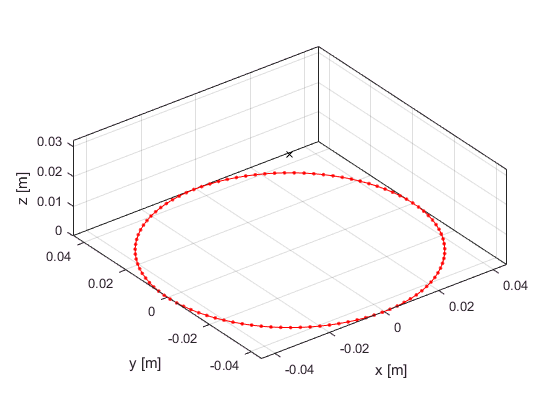

Bfield = Field(RX_LOC, tx);

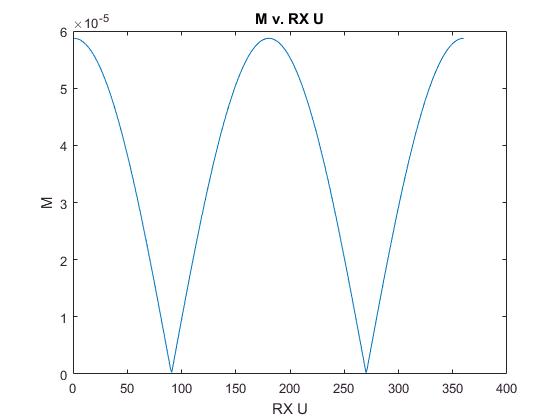


RX_FLUX = Bfield.B' * RX_U * rx.area();    % magnetic flux when I = 1
M = abs(rx.n_turns_total * RX_FLUX) / 1;           % mutual inductance, note that this is divided by I so it all works out

figure();
plot(M); xlabel('RX U'); ylabel('M'); title('M v. RX U');


% k = M / sqrt(TX_L .* RX_L)              % coupling constant

## Equivalent circuit

the transmitter and receiver coils can be modeled as two RLC circuits coupled through the inductors:

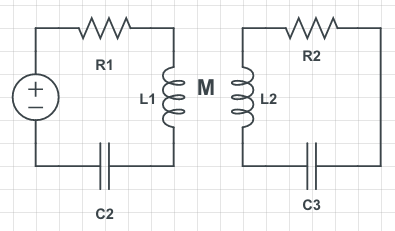

this gives an equivalent T-circuit:

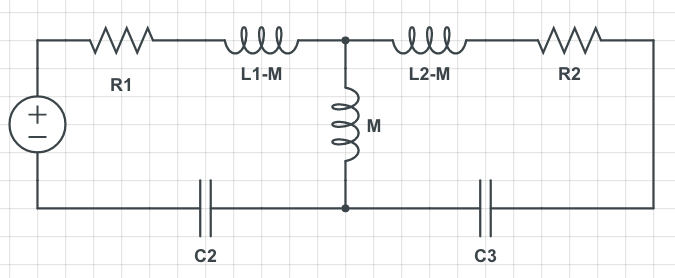

by Kirchoff's voltage law through the transmitter and receiver loops:


$$\begin{array}{l}
\left(R_1 +j\omega \left(L_1 −M\right)+j\omega M+\frac{1}{j\omega C_1 }\right)I_1 −j\omega M\text{ }I_2 =V\\
−j\omega M\text{ }I_1 +\left(R_2 +j\omega \left(L_2 −M\right)+j\omega M+\frac{1}{j\omega C_2 }\right)I_2 =0
\end{array}$$


define:


$$\begin{array}{l}
Z_1 =R_1 +j\omega L_1 +\frac{1}{j\omega C_1 }\\
Z_2 =R_2 +j\omega L_2 +\frac{1}{j\omega C_2 }\\
Z_M =j\omega M
\end{array}$$


and build a system of equations:


$$\left\lbrack \begin{array}{c}
Z_1  & −Z_M \\
−Z_M  & Z_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_1 \\
I_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
V\\
0
\end{array}\right\rbrack$$



$$\Delta =Z_1 Z_2 −Z_M^2$$


by Cramer's rule:


$$\begin{array}{l}
I_1 =\frac{\Delta_1 }{\Delta }=\frac{1}{Z_1 Z_2 −Z_M^2 }\left\lbrack \begin{array}{c}
V & −Z_M \\
0 & Z_2 
\end{array}\right\rbrack =\frac{{V\text{ }Z}_2 }{Z_1 Z_2 −Z_M^2 }\\
I_2 =\frac{\Delta }{\Delta }=\frac{1}{Z_1 Z_2 −Z_M^2 }\left\lbrack \begin{array}{c}
Z_1  & V\\
−Z_M  & 0
\end{array}\right\rbrack =\frac{V\text{ }Z_M }{Z_1 Z_2 −Z_M^2 }
\end{array}$$


the equivalent complex impedance seen by the voltage source is:


$$Z=\frac{V}{I_1 }=Z_1 −\frac{Z_M^2 }{Z_2 }$$


this can be used to derive the transmitter current and power as well.

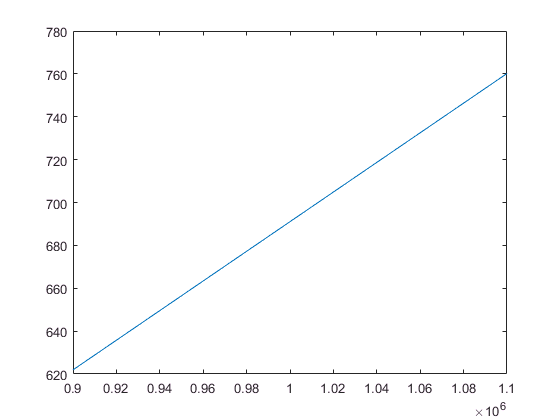

Z1 = tx.R + 1i.*OMEGA'*tx.L + 1./(1i.*OMEGA'.*tx.C);
figure(); plot(f, abs(Z1));

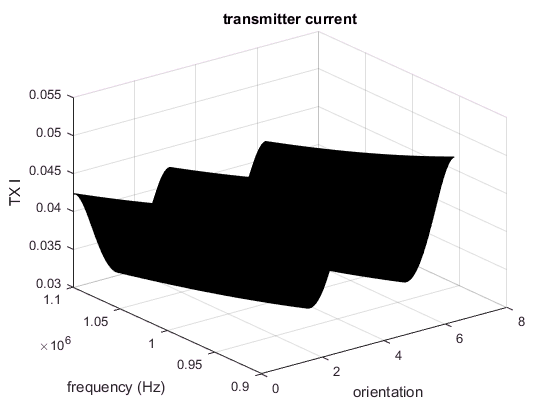

Z2 = rx.R + 1i.*OMEGA'*rx.L + 1./(1i.*OMEGA'.*rx.C);
ZM = 1i.*OMEGA'*M;

TX_Z = Z1 - ZM.^2 ./ Z2;    % complex impedance
TX_I = TX_V ./ TX_Z;
TX_P = TX_I .* TX_V;

figure(); surf(theta, f, abs(TX_I)); xlabel('orientation'); ...
    ylabel('frequency (Hz)'); zlabel('TX I'); title('transmitter current');

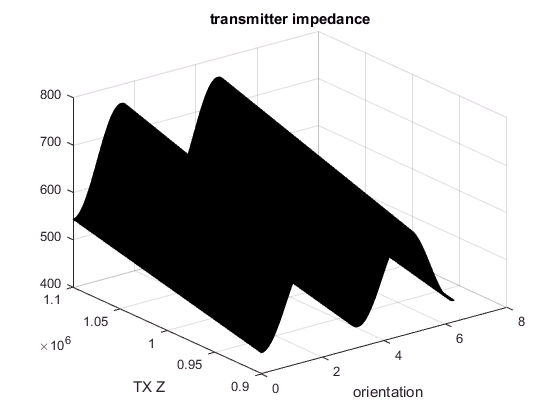

figure(); surf(theta, f, abs(TX_Z)); xlabel('orientation'); ...
    ylabel('frequency (Hz)'); ylabel('TX Z'); title('transmitter impedance');

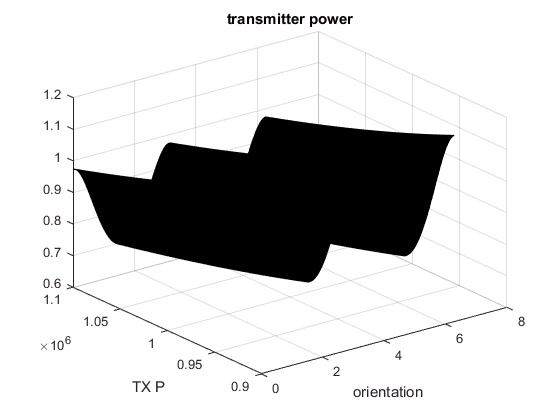

figure(); surf(theta, f, abs(TX_P)); xlabel('orientation'); ...
    ylabel('frequency (Hz)'); ylabel('TX P'); title('transmitter power');

The measured voltage across the transmitter is given by Ohm's law V = IR

To maximise this voltage across orientations, we need to maximise the reflected impedance term in the equation for impedance:


$$Z=Z_1 −\frac{Z_M^2 }{Z_2 }$$


Since $Z_M$varies with location and orientation, we must therefore minimise $Z_2$.


$$Z_2 =R_2 +j\omega L_2 +\frac{1}{j\omega C_2 }$$


As the system is resonant, we can assume the imaginary term is 0. Thus, we must minimise the resistance of the transmitting coil by either decreasing the number of turns (and thus the length of wire), or increasing the wire thickness (decreasing the wire gauge).

Notice that since ZM depends on the number of turns in the receiving coil, changing it will not increase the measurement. Thus, we must lower the resistance of the receiving coil by increasing the thickness/decreasing the wire gauge.

measurement = abs(TX_I * RX_R);

figure();
surf(theta, f, measurement); xlabel('orientation'); ...
    ylabel('frequency (Hz)'); zlabel('measurement (V)');

## Tx -> Rx coupling

Induced voltage in receiving coil:


$$V=−\omega N\varphi_{21}$$



$$\begin{array}{l}
\omega =\text{AC}\text{ }\text{frequency}\\
N=number\text{ }of\text{ }turns\text{ }in\text{ }\text{coil}\\
\varphi_{21} =\vec{B} \cdot \hat{n} ;\text{magnetic}\text{ }\text{flux}\text{ }\text{through}\text{ }one\text{ }turn\text{ }of\text{ }\text{receiving}\text{ }\text{coil}\text{ }\text{from}\text{ }\text{transmitting}\text{ }\text{coil}
\end{array}$$


TOTAL_RX_FLUX = bsxfun(@times, RX_NT*RX_NL * RX_FLUX, TX_I); % Wb
RX_V = -bsxfun(@times, OMEGA', TOTAL_RX_FLUX);    % induced voltage in receiver coil [V]

figure(); surf(theta, f, abs(RX_V)); title('receiver voltage');

receiver characteristics

- receiver impedance: by now switching the roles of the coils and using the receiving coil as the primary coil, we can derive the receiver impedance with the same method used for transmitter impedance


$$Z=Z_2 −\frac{Z_M^2 }{Z_1 }$$


RX_Z = Z2 - ZM .^2 ./ Z1;    % receiver impedance [Ohms]

figure(); plot(f, abs(RX_Z)); xlabel('frequency (Hz)'); ylabel('RX Z'); ...
    title('receiver impedance');

- receiver current


$$I=transient+I_0 sin\left(\omega t−\varphi \right)$$



$$I_0 =\frac{V_0 }{Z}$$



$$tan\left(\varphi \right)=\frac{\omega L−\frac{1}{\omega C}}{R}$$


RX_I = RX_V ./ RX_Z;    % receiver current [A]
RX_PHI = atan((OMEGA * RX_L - (1 ./ (OMEGA * RX_C))) / RX_R);
RX_P = RX_I .* RX_V;    % receiver power [W]

figure(); plot(f, abs(RX_I)); xlabel('frequency (Hz)'); ylabel('RX I'); ...
    title('receiver current');
figure(); plot(f, abs(RX_P)); xlabel('frequency (Hz)'); ylabel('RX P'); ...
    title('receiver power');

## Rx -> Tx coupling

Induced voltage:


$$V=M\frac{\mathit{dI}}{\mathit{dt}}$$


TX_DV = M' * OMEGA .* RX_I